### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
% Casts 
cast02 = readSBScnv( 'KN22104002_hyst.cnv' );
cast03 = readSBScnv( 'KN22104003_hyst.cnv' );
cast04 = readSBScnv( 'KN22104004_hyst.cnv' );
cast05 = readSBScnv( 'KN22104005_hyst.cnv' );
cast06 = readSBScnv( 'KN22104006_hyst.cnv' );
cast07 = readSBScnv( 'KN22104007_hyst.cnv' );
cast08 = readSBScnv( 'KN22104008_hyst.cnv' );
cast09 = readSBScnv( 'KN22104009_hyst.cnv' );

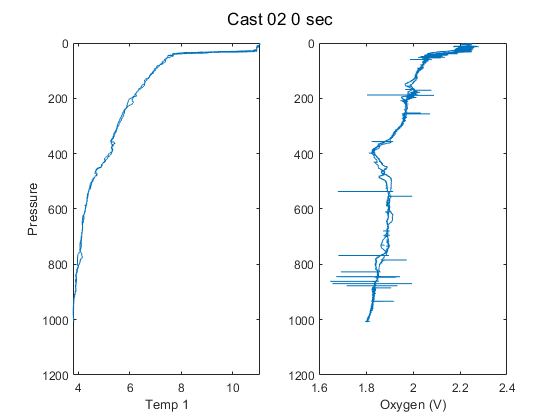

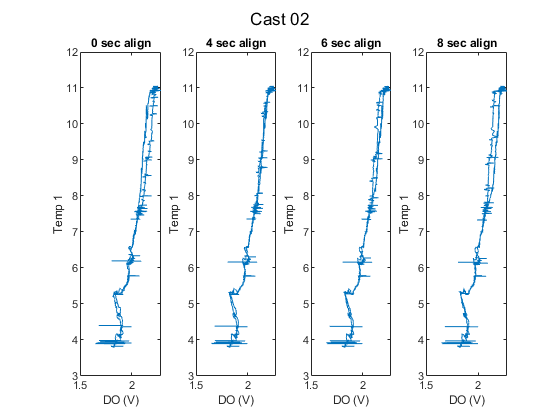

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 

cast02 = align_CTD_by_sensor_KF(cast02,'Cast 02',a1,a2,a3,CTD_sen1);

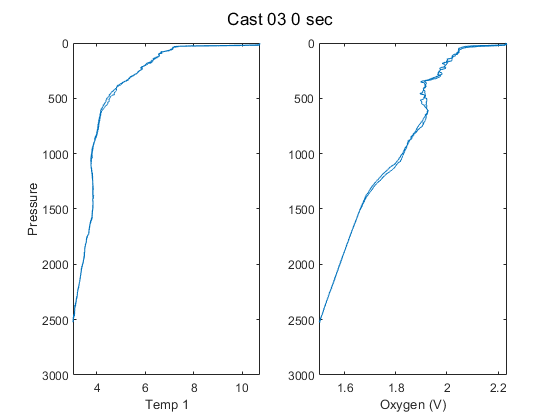

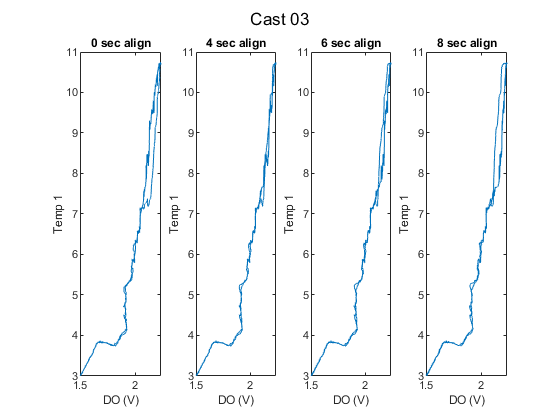

cast03 = align_CTD_by_sensor_KF(cast03,'Cast 03',a1,a2,a3,CTD_sen1);

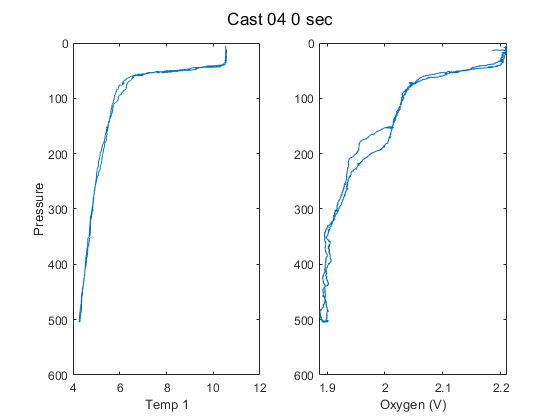

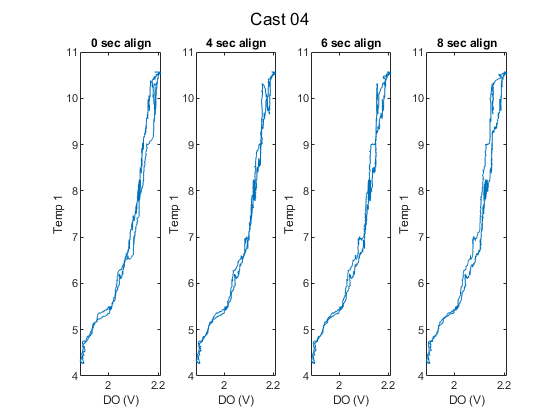

cast04 = align_CTD_by_sensor_KF(cast04,'Cast 04',a1,a2,a3,CTD_sen1);

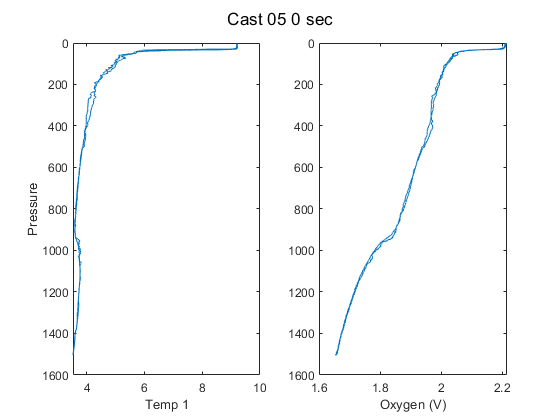

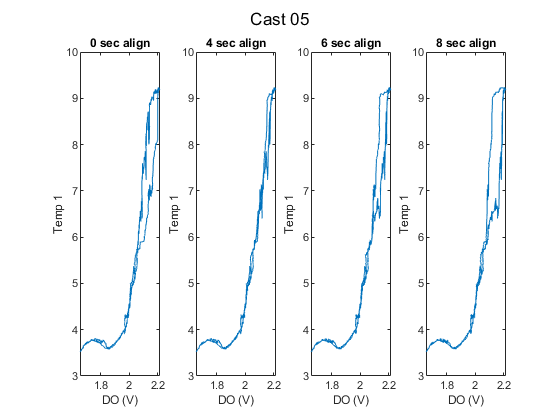

cast05 = align_CTD_by_sensor_KF(cast05,'Cast 05',a1,a2,a3,CTD_sen1);

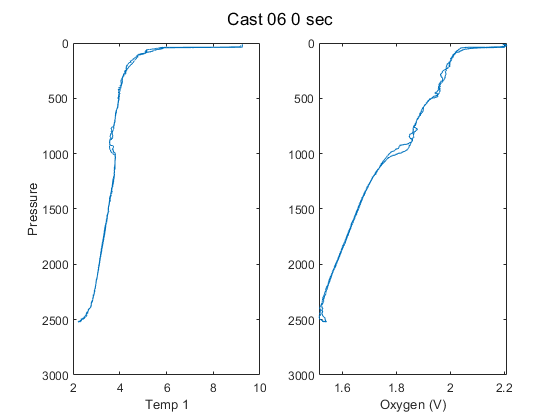

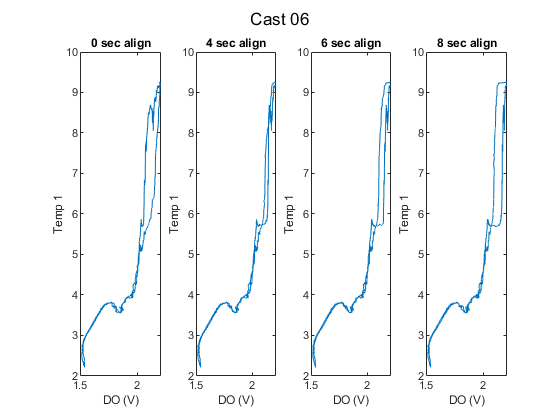

cast06 = align_CTD_by_sensor_KF(cast06,'Cast 06',a1,a2,a3,CTD_sen1);

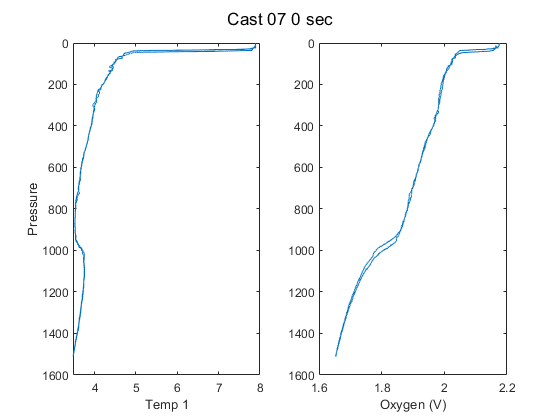

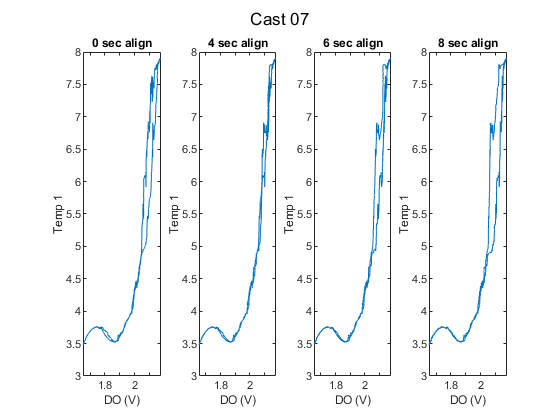

cast07 = align_CTD_by_sensor_KF(cast07,'Cast 07',a1,a2,a3,CTD_sen1);

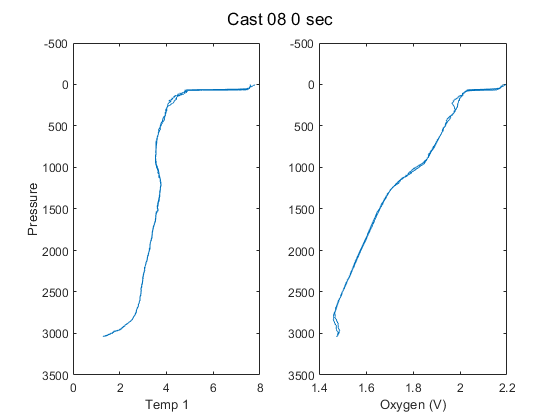

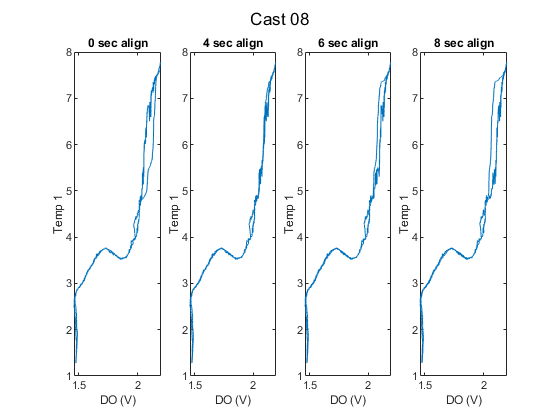

cast08 = align_CTD_by_sensor_KF(cast08,'Cast 08',a1,a2,a3,CTD_sen1);

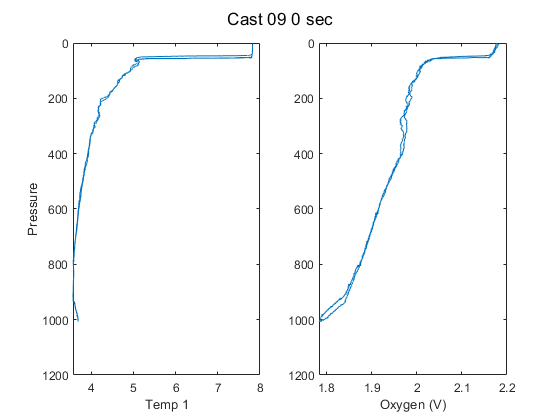

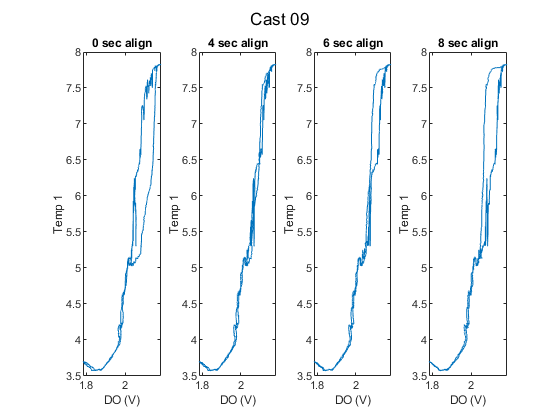

cast09 = align_CTD_by_sensor_KF(cast09,'Cast 09',a1,a2,a3,CTD_sen1);

% Pick align_sec
a1 = 4;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year1')
% addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1\From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')

btl = readtable('Irminger_Sea-01_KN221-04_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum02 = btl(btl.Cast == 2,:);
btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum09 = btl(btl.Cast == 9,:);

btlsum02 = combine_btl_files2('KN22104002.csv',btlsum02);

btlsum03 = combine_btl_files2('KN22104003.csv',btlsum03);

btlsum04 = combine_btl_files2('KN22104004.csv',btlsum04);

btlsum05 = combine_btl_files2('KN22104005.csv',btlsum05);

btlsum06 = combine_btl_files2('KN22104006.csv',btlsum06);

btlsum07 = combine_btl_files2('KN22104007.csv',btlsum07);

btlsum09 = combine_btl_files2('KN22104009.csv',btlsum09);


%% If get finalized finalsfrom Leah 
% btlsum02 = combine_btl_files('KN22104002.cbot_s','KN22104002.csv',btlsum02,CTD_sen1);
% btlsum03 = combine_btl_files('KN22104003.cbot_s','KN22104003.csv',btlsum03,CTD_sen1);
% btlsum04 = combine_btl_files('KN22104004.cbot_s','KN22104004.csv',btlsum04,CTD_sen1);
% btlsum05 = combine_btl_files('KN22104005.cbot_s','KN22104005.csv',btlsum05,CTD_sen1);
% btlsum06 = combine_btl_files('KN22104006.cbot_s','KN22104006.csv',btlsum06,CTD_sen1);
% btlsum07 = combine_btl_files('KN22104007.cbot_s','KN22104007.csv',btlsum07,CTD_sen1);
% btlsum09 = combine_btl_files('KN22104009.cbot_s','KN22104009.csv',btlsum09,CTD_sen1);

btlsum_yr1 = [btlsum02; btlsum03; btlsum04; btlsum05; btlsum06; btlsum07; btlsum09];
btlsum0 = btlsum_yr1; %

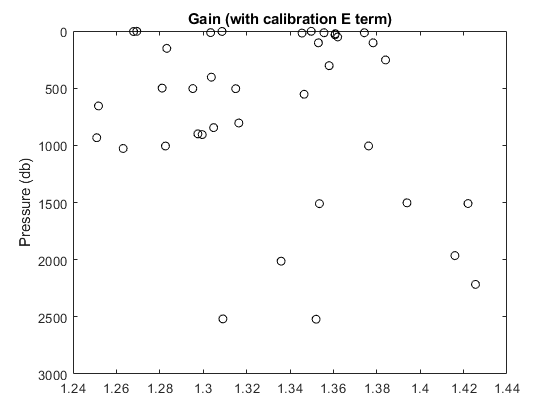

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Oxygen Sensor for cast 2 on; different one cast 1  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.55930e-001);
cal.VOFFSET = double(-4.97100e-001);
cal.A = double(-3.66900e-003);
cal.B = double(1.91110e-004);
cal.C = double(-2.62760e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(2.23000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1679';
cal.OCALDATE = '23-Oct-13';

H = [-0.033, 5000, 1450]; % Default 

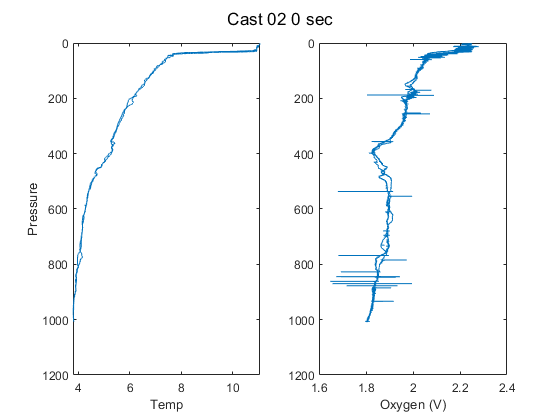

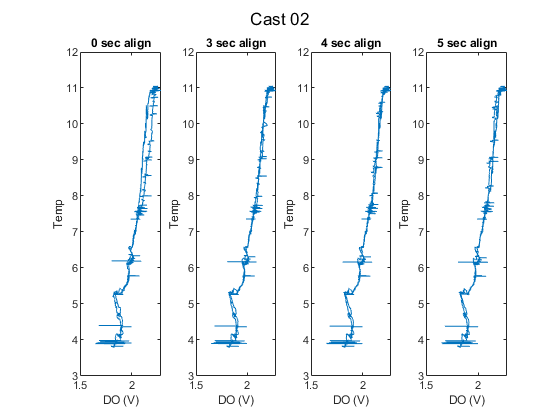

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 3; a2 = 4; a3 = 5;

% cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);
cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

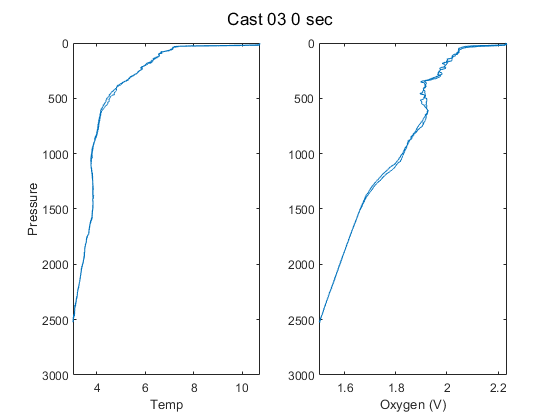

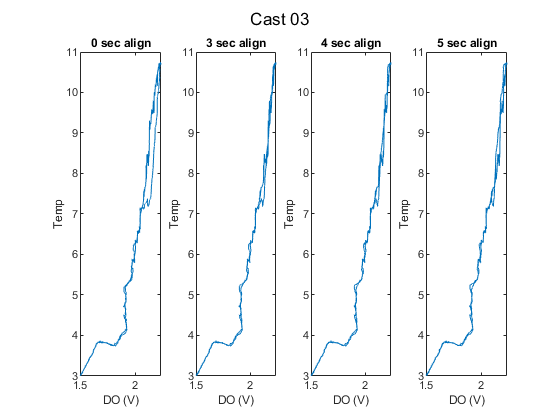

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

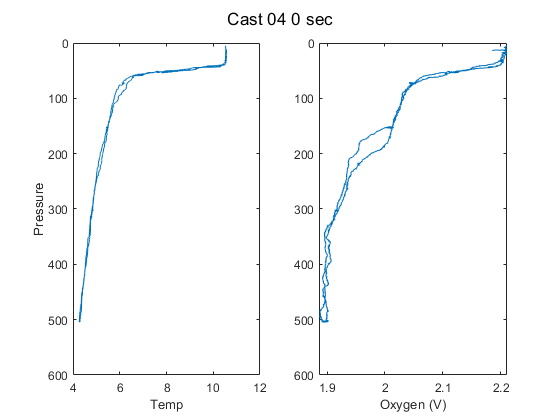

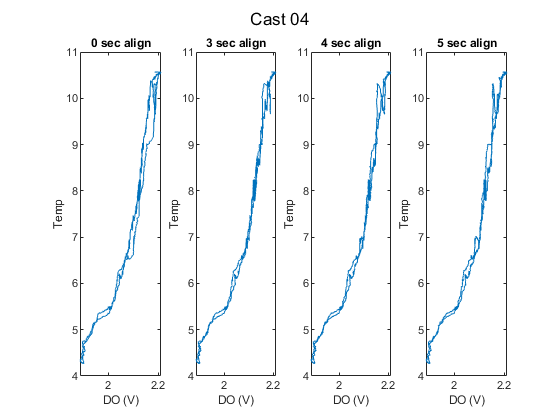

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

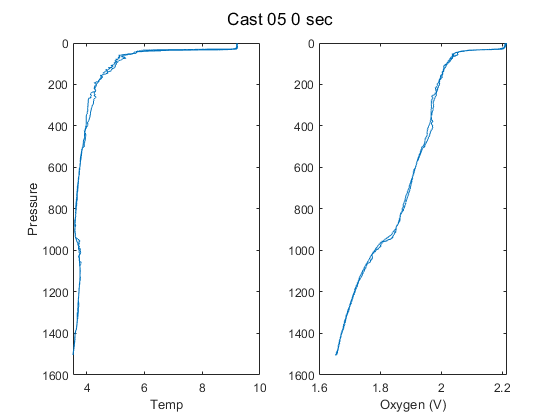

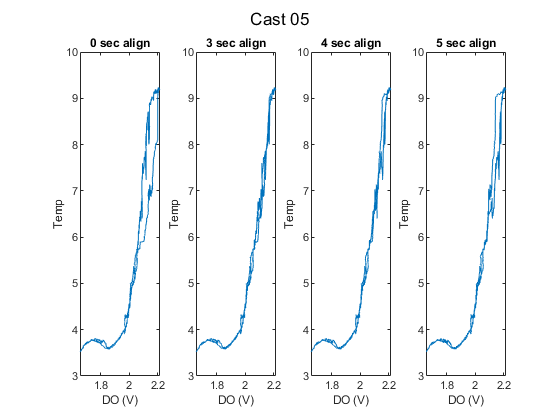

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

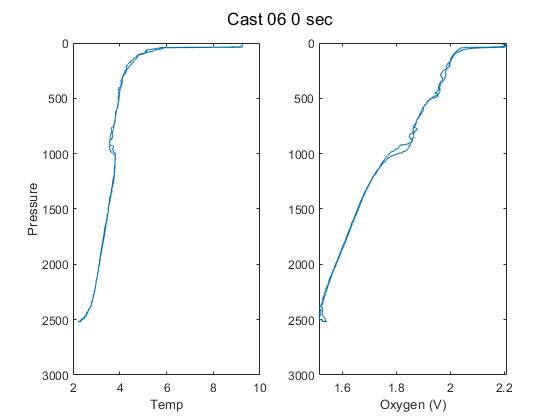

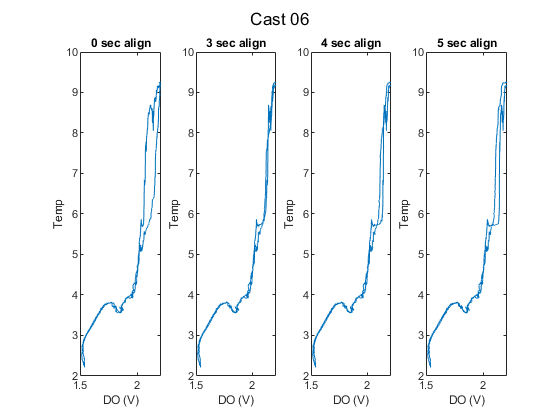

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

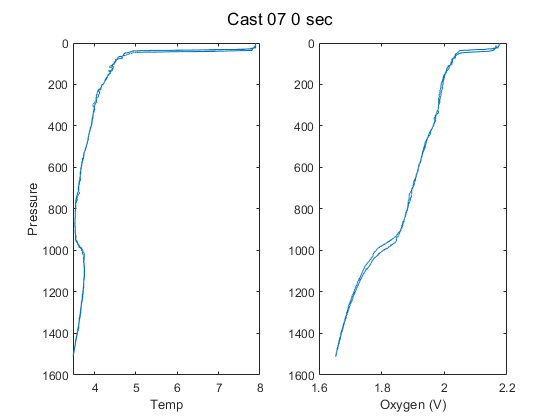

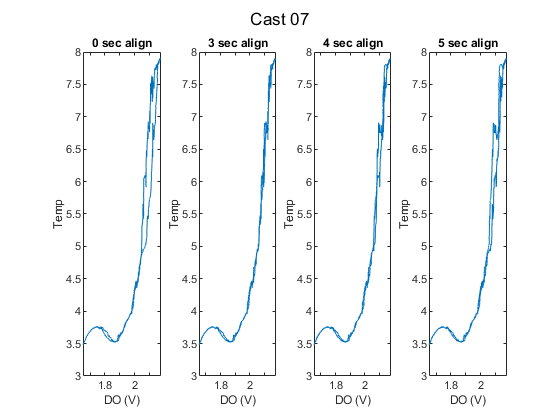

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

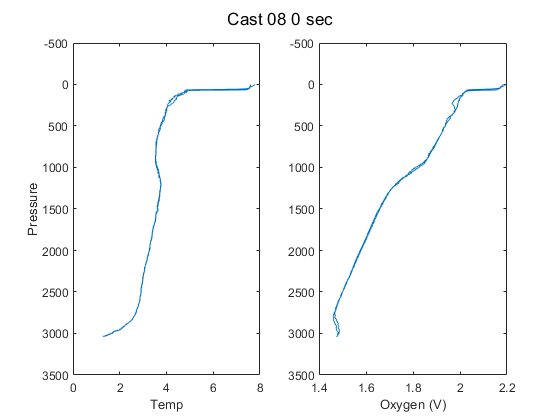

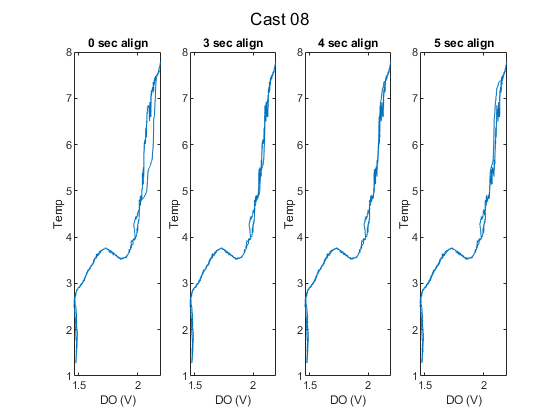

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

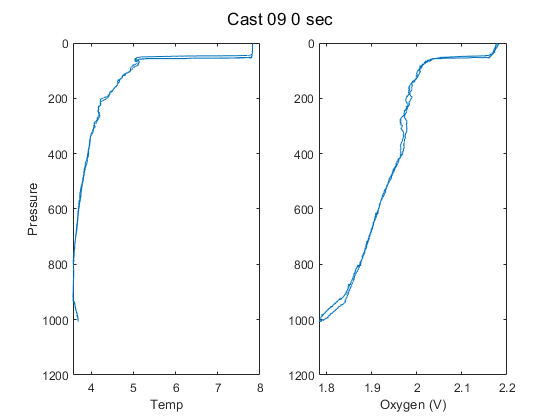

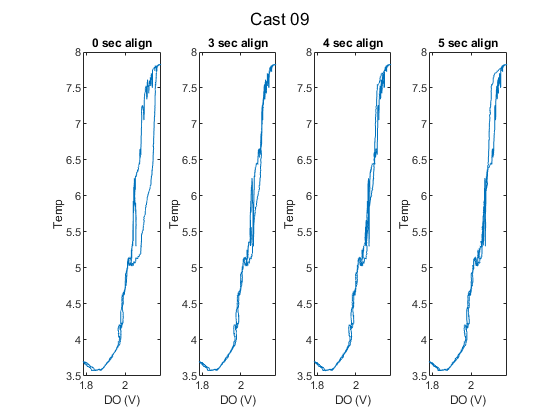

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);


% Pick align_sec

align_sec = a2; 


% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
cast02 = readSBScnv( 'uKN22104002_hyst_abcdefg.cnv' );
cast03 = readSBScnv( 'uKN22104003_hyst_abcdefg.cnv' );
cast04 = readSBScnv( 'uKN22104004_hyst_abcdefg.cnv' );
cast05 = readSBScnv( 'uKN22104005_hyst_abcdefg.cnv' );
cast06 = readSBScnv( 'uKN22104006_hyst_abcdefg.cnv' );
cast07 = readSBScnv( 'uKN22104007_hyst_abcdefg.cnv' );
cast08 = readSBScnv( 'uKN22104008_hyst_abcdefg.cnv' );
cast09 = readSBScnv( 'uKN22104009_hyst_abcdefg.cnv' );

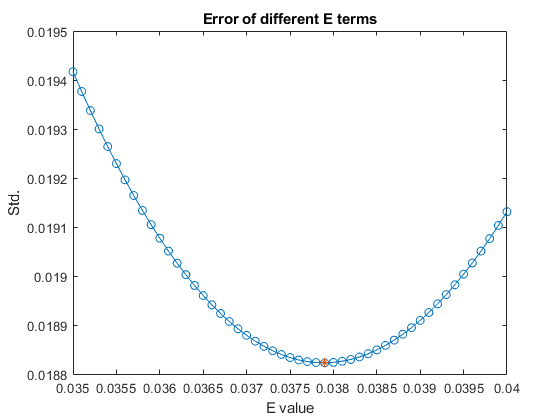

cal.E2 = 0.0379


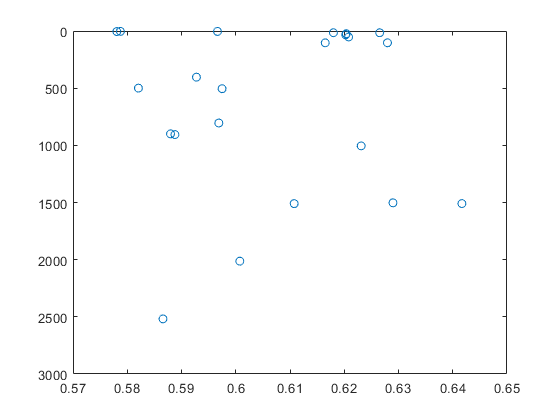

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
[cal] = E2_calculation(btlsum0,cal); % Use dummy bottle summary with outlier removed

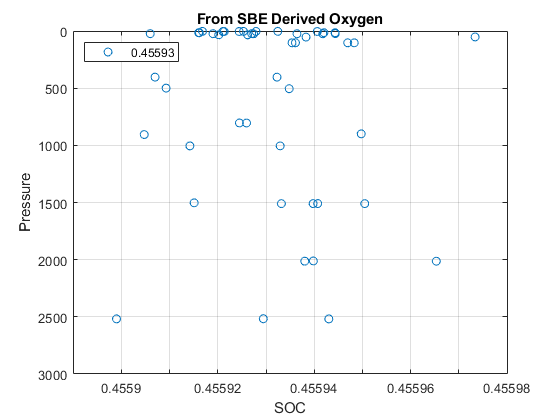

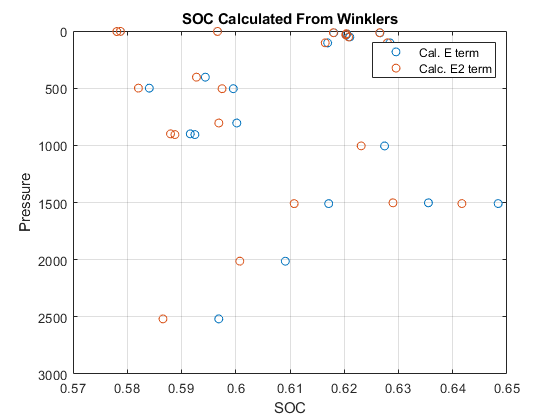

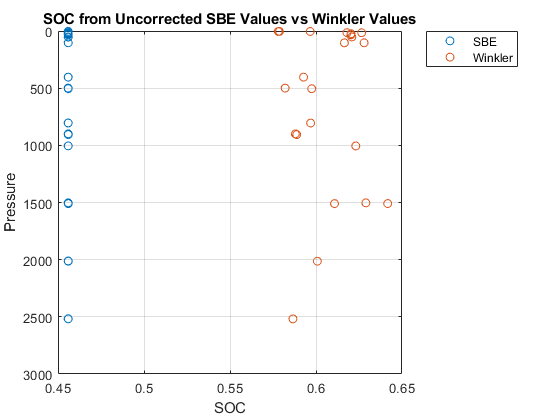

New SOC = 0.60644
EGain = 1.3301+/- 0.041284


[cal] = Gain_E2_Calculation(btlsum0,cal); % Use dummy bottle summary with any outliers removed

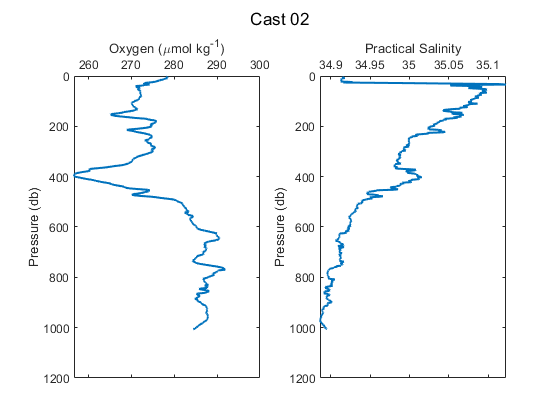

[cast02, btlsum02] = Process_Cast_Gain_E2(cast02,cal,0,1,'Cast 02');

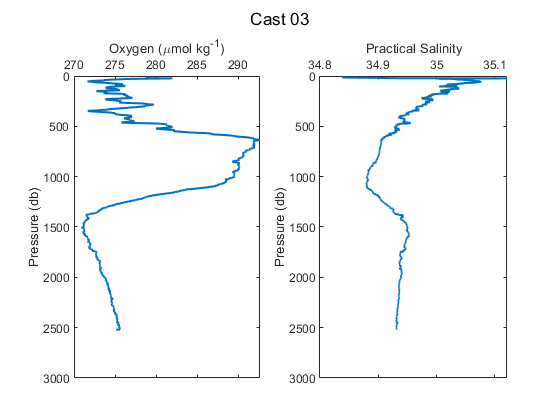

[cast03, btlsum03] = Process_Cast_Gain_E2(cast03,cal,0,1,'Cast 03');

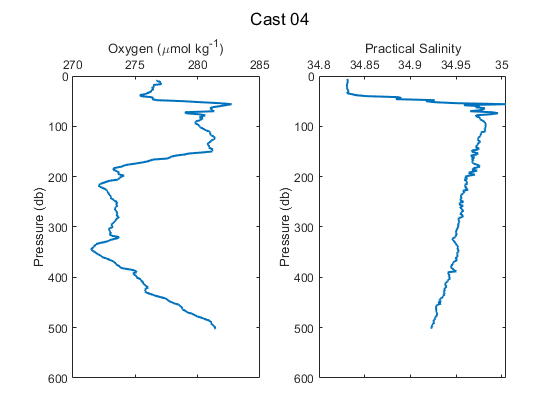

[cast04, btlsum04] = Process_Cast_Gain_E2(cast04,cal,0,1,'Cast 04');

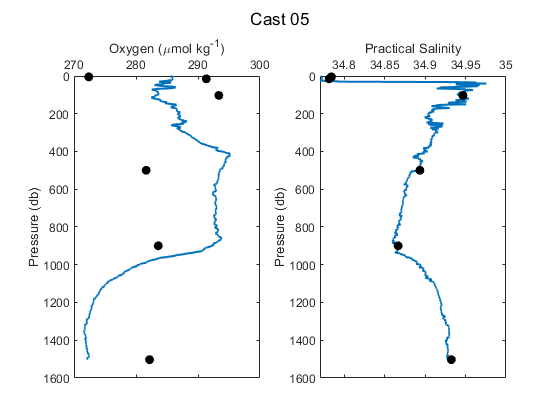

[cast05, btlsum05] = Process_Cast_Gain_E2(cast05,cal,btlsum05,1,'Cast 05');

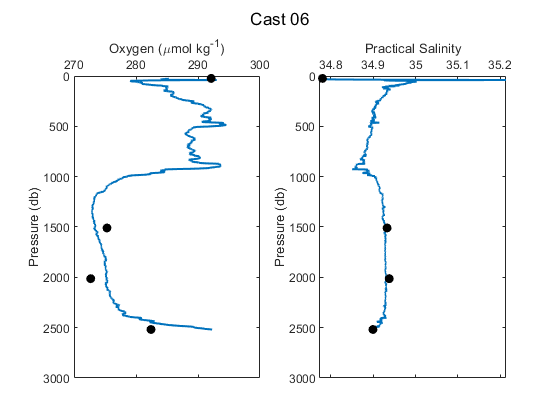

[cast06, btlsum06] = Process_Cast_Gain_E2(cast06,cal,btlsum06,1,'Cast 06');

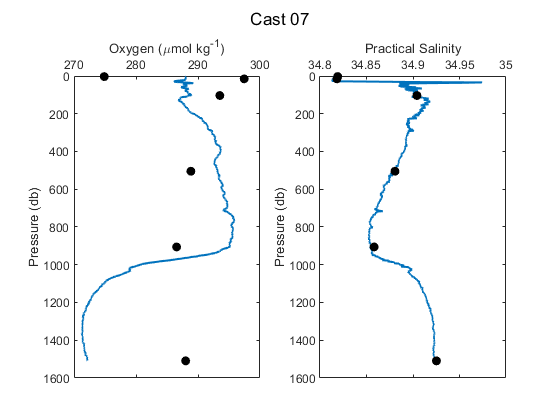

[cast07, btlsum07] = Process_Cast_Gain_E2(cast07,cal,btlsum07,1,'Cast 07');

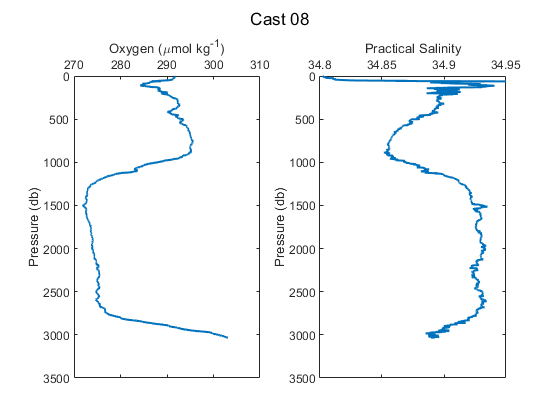

[cast08, btlsum08] = Process_Cast_Gain_E2(cast08,cal,0,1,'Cast 08');

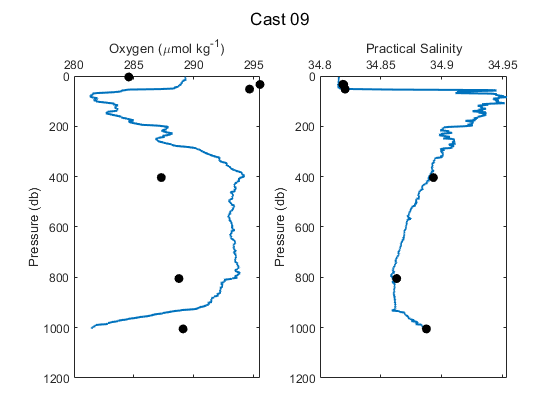

[cast09, btlsum09] = Process_Cast_Gain_E2(cast09,cal,btlsum09,1,'Cast 09');

btlsum_yr1 = [btlsum05; btlsum06; btlsum07; btlsum09];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0379


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.45593


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.60644


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.3301+/- 0.041284


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
clear btlsum0
dt_Processed = datetime;
save Year1_Processed_KF cast* btl* cal* dt_Processed 



